%% 捕食者与竞争者模型

clear; clc

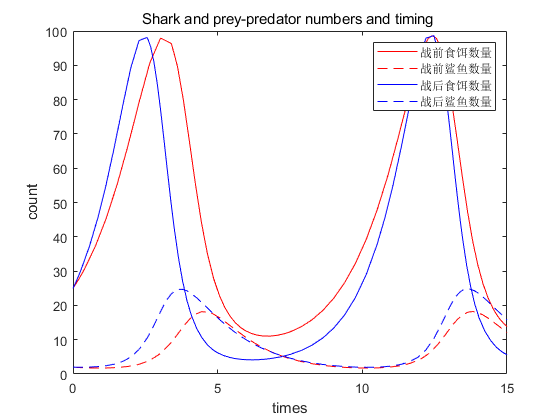


% 求解微分方程
% 其中设自变量t的范围: 0~15, 食饵和捕食者初始值为25和2
[t1, x1] = ode45('pre_war', [0, 15], [25, 2]); % 战前的微分方程
[t2, x2] = ode45('post_war', [0, 15], [25, 2]); % 战后的微分方程
% 其中x1是战前的微分方程, x(1)是食饵的数量, x(2)是鲨鱼的数量.
% x2同理, 是战后的微分方程, x(1)是食饵的数量, x(2)是鲨鱼的数量.
% t就是我们的时间, 看ode45, 将我们的时间分解成多少个间隔

pre_prey=x1(:,1); pre_shark=x1(:,2);   % 战前的食饵和鲨鱼的数量
post_prey=x2(:,1); post_shark=x2(:,2);  % 战后的食饵和鲨鱼的数量


% 画图:
figure(1);
% 鲨鱼和食饵数量变化的相轨线图
plot(pre_prey, pre_shark, "r--", post_prey, post_shark, '-b')
legend("befor war", "after war"); % 添加legend
title("Before ad after the war"); % 鲨鱼和食饵数量变化的
xlabel('prey num');
ylabel('shark num');

% 看一下与鲨鱼和食饵数量和时间的关系
figure(2);  
plot(t1, pre_prey, "-r", t1, pre_shark, "--r", t2, post_prey, '-b', t2, post_shark, '--b');
title("Shark and prey-predator numbers and timing ");
legend('战前食饵数量','战前鲨鱼数量','战后食饵数量','战后鲨鱼数量');
xlabel("times"); ylabel("count");

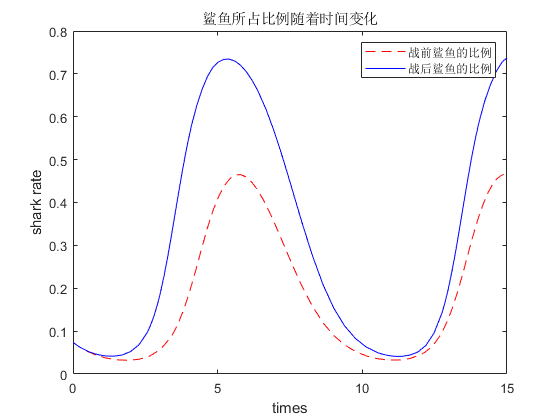


% 最后看一下比例随着时间变化:
% 鲨鱼比例 = 鲨鱼数量 / (鲨鱼数 + 食饵数)
pre_rate = pre_shark./(pre_prey+pre_shark); % 战前鲨鱼的比例
post_rate=post_shark./(post_prey+post_shark); % 战后鲨鱼的比例
figure(3);
plot(t1, pre_rate, '--r', t2, post_rate, '-b');
legend("战前鲨鱼的比例", "战后鲨鱼的比例");
title("鲨鱼所占比例随着时间变化");
xlabel('times'); ylabel("shark rate");